% Input file must be in the form of HEX ASCII
% Example: AA BB 12 FF DB 34...

filename = 'speedtest.txt';

q = quantizer('fixed', 'nearest', 'saturate', [10 0]);% quantizer object for num2hex function  
FID = fopen(filename)

FID = 3


dataFromfile = textscan(FID, '%s');% %s for reading string values (hexadecimal numbers)
dataFromfile = dataFromfile{1};
decData = hex2num(q, dataFromfile);
decData = cell2mat(decData);
fclose(FID);

dataFromfile

dataFromfile = 151792×1 cell array
    {'AA'}
    {'BB'}
    {'69'}
    {'25'}
    {'00'}
    {'00'}
    {'00'}
    {'00'}
    {'AA'}
    {'BB'}
    {'43'}
    {'25'}
    {'00'}
    {'00'}
    {'00'}
    {'00'}
    {'AA'}
    {'BB'}
    {'26'}
    {'25'}
    {'00'}
    {'00'}
    {'00'}
    {'00'}
    {'AA'}
    {'BB'}
    {'08'}
    {'25'}
    {'00'}
    {'00'}



state = 0

state = 0

stop = 1;
k = 1;
tt = 1;
word = cell(50000,1);
final = cell(50000,1);
while(k ~= numel(dataFromfile) - 7)
    
    if(dataFromfile{k} == 'BB' & dataFromfile{k+7} == 'AA')
        word{tt} = strcat(dataFromfile{k+6}, ...
            dataFromfile{k+5}, ...
            dataFromfile{k+4}, ...
            dataFromfile{k+3}, ...
            dataFromfile{k+2}, ...
            dataFromfile{k+1});
    end
    tt = tt + 1;
    k = k + 1;
end

word = word(~cellfun('isempty',word))

word = 18973×1 cell array
    {'000000002569'}
    {'000000002543'}
    {'000000002526'}
    {'000000002508'}
    {'0000000024DF'}
    {'0000000024B7'}
    {'0000000024A8'}
    {'0000000024A2'}
    {'00000000249F'}
    {'000000002480'}
    {'000000002443'}
    {'0000000023DB'}
    {'000000002380'}
    {'00000000233E'}
    {'000000002313'}
    {'0000000022FE'}
    {'0000000022F0'}
    {'0000000022D9'}
    {'0000000022CE'}
    {'0000000022E2'}
    {'000000002308'}
    {'00000000232B'}
    {'000000002332'}
    {'00000000230F'}
    {'0000000022EC'}
    {'0000000022C5'}
    {'0000000022B7'}
    {'0000000022BF'}
    {'0000000022CF'}
    {'0000000022D0'}


word = hex2dec(word)

word =         9577
        9539
        9510
        9480
        9439
        9399
        9384
        9378
        9375
        9344


word = word + 1;
%word = (1/(20 * 500 * (10^-9))).*(1./word)
word = 100000./word

word = 	1.0e+05 *

    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001



word(word>22) = []

word =    10.4406
   10.4822
   10.5141
   10.5474
   10.5932
   10.6383
   10.6553
   10.6621
   10.6655
   10.7009


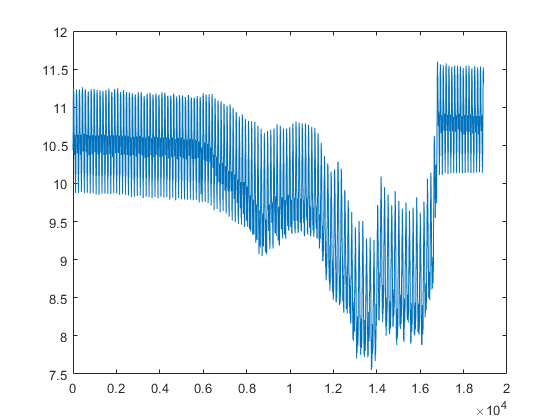

plot(word)